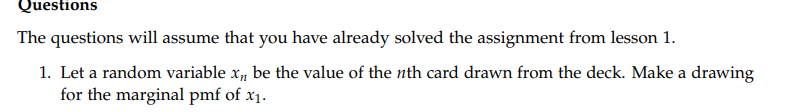

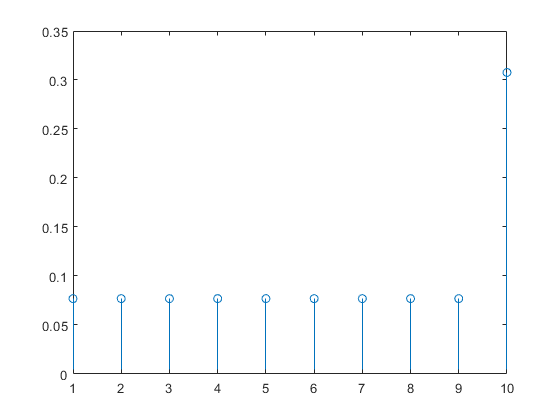

%% Question 1 - marginal pmf pr(x_1)

numbers=1:10;

card_values=[1:10,10,10,10,1:10,10,10,10,1:10,10,10,10,1:10,10,10,10]';
%plot af pmf, we define that ace has a value of 1
[a b]=hist(card_values);
stem(numbers,a./sum(a))

Pr_x1=a./sum(a);

%% Question 2 - Expected value of x_1
Mean_x1=sum((a./sum(a)).*numbers);
disp(['x1 = ', num2str(Mean_x1)])

x1 = 6.5385


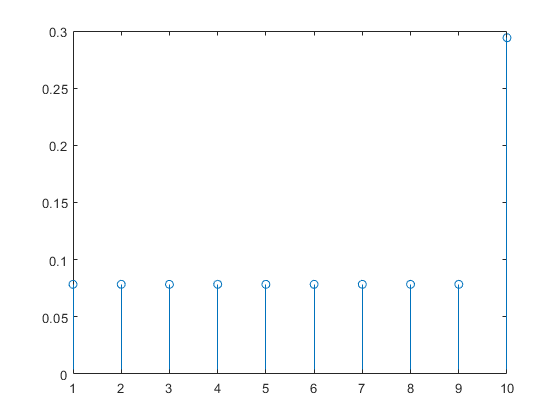


%% Question 3 -  10 drawn first card, pmf for second card
numbers=1:10;

card_values=[1:10,10,10,1:10,10,10,10,1:10,10,10,10,1:10,10,10,10]';
%plot af pmf, we define that ace has a value of 1
[a b]=hist(card_values);
figure(2)
stem(numbers,a./sum(a))

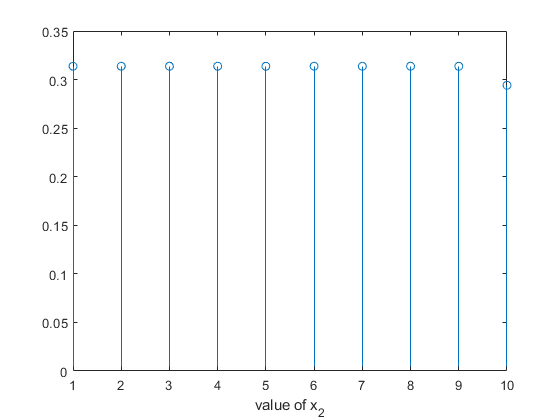

Pr_x2_givet_x1=a./sum(a);

%verification of result
nMCruns=1000;
cards=shufflecards();
MM=0;
card2=[];

for n=1:nMCruns
    cards=shufflecards();
    if cards(1).value == 10
        card2=[card2 cards(2).value];
        MM=MM+1;
    end
end
[a b]=hist(card2);
a./sum(a);

%% Question 4 -- find pr(x_1=10|x_2)
% Pr(x_1=10)= Pr_x1(end)
% Pr(x_1)=Pr(x_2)
Pr_x2=Pr_x1;
Pr_x1_givet_x2=Pr_x2_givet_x1./Pr_x2.*Pr_x1(end);

% We plot Pr(x_1=10|x_2)
figure(3)
stem(numbers, Pr_x1_givet_x2)
xlabel('value of x_2')

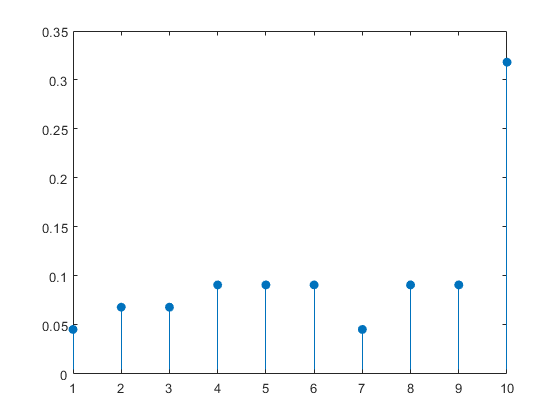

ans =     0.0455    0.0682    0.0682    0.0909    0.0909    0.0909    0.0455    0.0909    0.0909    0.3182



%% Question 5 - Verification of results for question 4
nMCruns=100000;

MM=0;
card2=[];
cards1=zeros(1,10);
for n=1:nMCruns
    cards=shufflecards();
    
    index=cards(2).value;
    if cards(1).value == 10
        cards1(index)=cards1(index)+1;
    end
    card2=[card2 cards(2).value];
end
[a b]=hist(card2);

simpr1_givetPr2=cards1.*a./sum(a);
%normalisering
%max(Pr_x1_givet_x2)./max(simpr1_givetPr2)
simpr1_givetPr2=simpr1_givetPr2.*max(Pr_x1_givet_x2)./max(simpr1_givetPr2);
%simpr1_givetPr2=simpr1_givetPr2./nMCruns

%% Question 6 -- conditional pmf for nth card

%function for finding the conditional pmf based on previous drawn cards
cond_nth_card([1 2 10 10 1 3 7 7])% example

ans = 6.7955


%% Question 7
% The expected value
sum((1:10).*(cond_nth_card([1 2 10 10 1 3 7 7])))

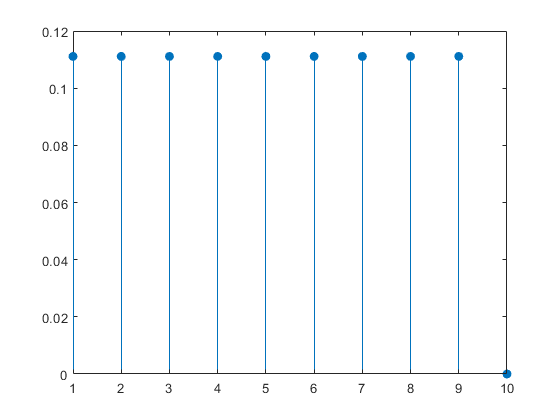

ans = -2.2204e-16


%% Question 8 -- calculate bust risk -test

bust_risk([10 2],ones(16,1).*10)

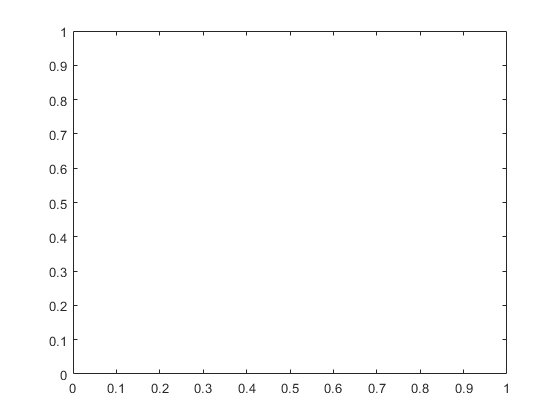


%% Question 9 Player strategy
% if probabiilty of busting is less than 0.5, keep playing

%% Question 10 _ simulation of new strategy
% shuffle he cards
cards=shufflecards();
drawncards=[];
newgame=1;
dealer=0;
player_value=[];
dealer_value=[];
for Number_we_are_at=1:52
    
    if newgame ==1     % new game, same deck
        cards_on_tabel=cards(Number_we_are_at).value;
    newgame =0; 
    else
        cards_on_tabel=[cards_on_tabel cards(Number_we_are_at).value];
    end
    drawncards=[drawncards cards(Number_we_are_at).value];
    
    
    if dealer == 1 %dealer plays
        
        if sum(cards_on_tabel) >=playervalue(end)
            dealer_value=[dealer_value sum(cards_on_tabel)];
            newgame=1;
            dealer=0;
        end
   else
        if sum(cards_on_tabel)== 21
            player_value=[player_value sum(cards_on_tabel)];
            newgame=1;
            dealer=1;% dealer plays
        else if sum(cards_on_tabel)> 21
                newgame=1;
            dealer=0;% dealer does not need to playes
            player_value=[player_value 0];
            dealer_value=[dealer_value 21];
            else
        risk=bust_risk(cards_on_tabel,drawncards);
        if risk>1 %stop game
            player_value=[player_value sum(cards_on_tabel)];
            newgame=1;
            dealer=1;% dealer playes
        else
            newgame=0;
        end
            end
        end
    end
end


%% Question 11
% No her cannnot

%% Question 12
% More unpredictable